# Machine Learning for Regression: Part 1

*A light introduction*

**Suggested Pre-work**

[MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted) – a free two-hour introductory tutorial to learn the essentials of MATLAB.

## 1. What is Machine Learning?

Machine Learning refers to a set of models and algorithms that automatically **learn** information from data. It can be seen as a data-driven approach to approximate a function if the actual function is unknown. Such models are used for: 

- ***Clustering****: *Grouping data and finding hidden patterns.

- ***Classification****: *Assigning to known discrete categories.

- ***Regression****: *Predicting continuous-valued responses.

***Task:**** Use the drop-down control to view an example of each of regression, classification, and clustering problems.*

ShowRegression; 

Broadly, there are two types of machine learning algorithms:

- **Supervised algorithms** need labeled training data. The algorithm learns a relationship based on the labeled data and applies it to new unseen data. Supervised algorithms are used for **classification** and **regression**. 

- **Unsupervised algorithms**, on the other hand, do not need labeled data and are used for **clustering**.

The high-level workflow for machine learning is similar to a general data analysis workflow. Here is an overview of the steps involved:

In practice, you will iterate several times between the **preprocessing**, **feature engineering**, and **model development** stages before deploying your final model. This module focuses on using machine learning to formulate and solve regression problems.

## 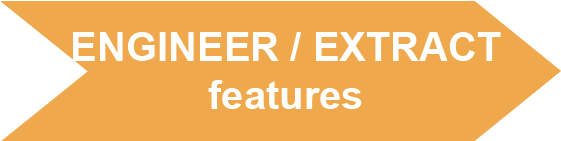

## 2. Feature Engineering

Machine learning models use **features** (or **predictors**) to find patterns and make predictions. For example, a used car’s make, age, and mileage help predict its price, while its exact registration date may not.

**Feature engineering** selects useful information from raw data, and **feature extraction** converts it into numeric **feature vectors**. The goal is to remove redundancy and retain the information most useful to the model.

While most practical machine learning problems will involve multiple features, you will now explore a few simple examples of 1-D data and engineer a single feature. 

***Task:**** Click the ****Test feature**** button to run this section. Your goal is to fit a simple linear regression model using the engineered feature *`x1`*.*

rng(42);                        % Set random number generator seed
x = rand(21,1);                 % Generate x for sample data.
y = 0.5 + sin(2*pi*x)*0.5 + 0.21*rand(size(x));

% Create a feature vector by transforming the original data.
x1 = x;
 

TestFeature(x,y,x1);

## 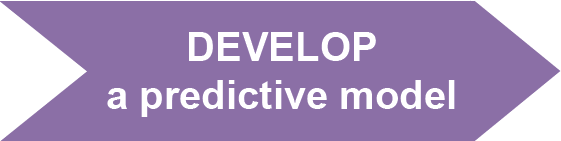

## 3. Some Machine Learning Models

Common regression models include:

- Linear Regression

- Stepwise Linear Regression

- Regression Tree

- Ensemble of Trees

### 3.1. Linear Regression

Regression is a statistical method for estimating the relationship between a **dependent variable** and one or more **independent variables**. In machine learning, the dependent variable is called the **response**, while the independent variables are called **features** or **predictors**.

A regression model predicts a continuous-valued response from these predictors. **Linear regression** assumes that the model is linear in its coefficients. When it uses multiple predictors to predict one response, it is called **multiple linear regression**.

A multiple linear regression model is

                    $y_i =\beta_o +\beta_1 X_{\mathrm{i1}} +\beta_2 X_{\mathrm{i2}} +\beta_3 X_{\mathrm{i3}} +\ldotp \ldotp \ldotp \beta_p X_{\mathrm{ip}} +\varepsilon_i$           $i=1,2,\ldotp \ldotp \ldotp n$,

where

- $y_i$ is the $i$th response

- $\beta_k$ is the $k$th coefficient and $\beta_0$ is the constant term

- $X_{\mathrm{ij}}$ is the $i$th observation on the $j$th predictor variable, $j=1,2,\ldotp \ldotp \ldotp p$

- $\varepsilon_i$ is the $i$th noise term or random error

### **3.2. Stepwise Linear Regression**

A stepwise linear regression model adds or removes predictors one at a time based on a chosen criterion. This process combines feature selection with model fitting by keeping predictors that help explain the response and removing those that do not.

***Task: ****Click the ****Fit linear regression model**** button to apply stepwise linear regression. Then, follow the subsequent instructions.*

*a. ****Task*****:** Select the number of predictors to generate a dataset. For the first run, use 6 predictors.

NumPredictors = 6; % Number of predictors to include in the sample data
[X,y] = GenerateData(NumPredictors);       % Generate some random data samples to perform regression

*b. ****Task*****: **Check the size of the generated variables `X` and `y`. `X` contains the observations along its rows and predictors along its columns (1 to NumPredictors). `y` has the response for each observation.

whos X y                                   % Display the size of X and y

First, fit a constant linear regression model to create a starting model for stepwise regression. 

*c. ****Task*****:** Observe the resulting model in the output below.

StartingMdl = fitlm(X,y,"constant")

Next, add or remove terms to improve the starting model in steps. Set the final model to be a linear regression model.

*d. ****Task*****:** Observe the output to see which terms are added or removed.

for N = 1:20
    UpdatedMdl = step(StartingMdl,"Upper","linear");
    StartingMdl = UpdatedMdl;
end

*e. ****Task*****:** View the final linear regression model. Specifically, note which terms or predictors are included in the final model.

disp(UpdatedMdl)

### 3.3. Regression Tree

A decision tree is a supervised learning model that captures complex, nonlinear relationships using a sequence of if-else rules. Its structure consists of a **root**, **branches**, **nodes**, and **leaves**:

- The **root** is the starting point.

- A **node** splits the data according to a rule.

- A **branch** represents the result of a split.

- A **leaf** provides the final prediction.

                                        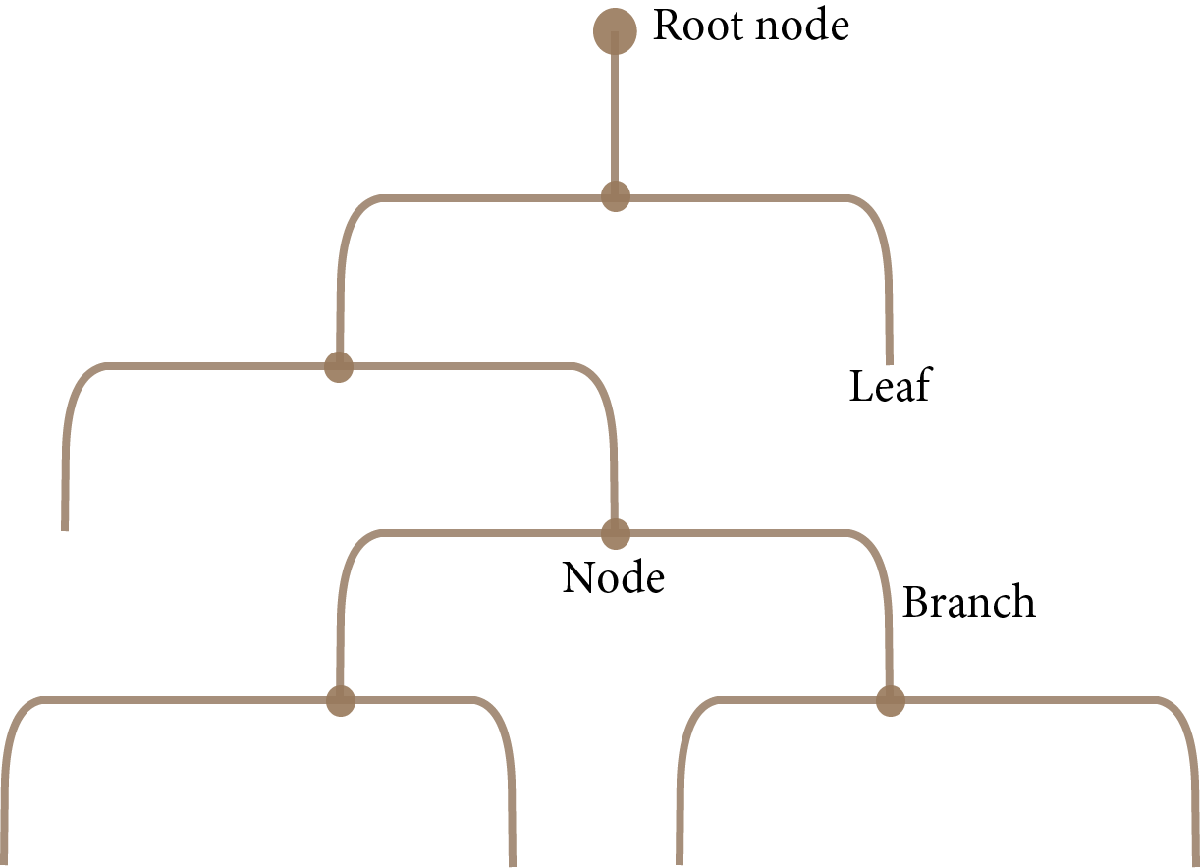

Decision trees can perform **classification** or **regression**. When predicting a continuous value, the model is called a **regression tree**. It repeatedly divides the training data into subsets using selected predictors and threshold values. Its structure depends on settings such as the number of splits, the minimum number of observations per leaf, and the criteria used to select each split.

***Task:**** Click ****Fit regression tree**** to view an example of a regression tree to model the hourly electricity load in a day.*

load LoadMayDay.mat x y
NumSplits =2;
 

ShowRegressionTree(x,y,NumSplits);

### **3.4. Ensemble of Trees**

A **weak learner** performs only slightly better than random guessing, while a **strong learner** makes more accurate predictions. Ensemble learning combines several weak learners to create a stronger model. Shallow regression trees are often used because their complexity can be controlled through their depth. A group of such trees is called an **ensemble of trees**.

Two common ensemble methods are **bagging** and **boosting**.

**Bagging** (bootstrap aggregation) trains separate trees on different bootstrap samples of the training data. Each sample is created by selecting `N` observations from a dataset of size `N`, with replacement. Some observations may therefore appear multiple times, while others are omitted. The omitted observations are called **out-of-bag observations**. Predictions from all trees are then combined, usually by averaging for regression.

**Boosting** trains trees sequentially. Each new tree focuses more on observations that previous trees predicted poorly. The trees’ predictions are then combined, with each tree’s contribution determined by the boosting method.

***Task:**** Click ****Fit ensemble of trees**** to view an example to model the hourly electricity load in a single day.*

load LoadMayDay.mat x y
NumTrees = 2;
NumSplits = 1;
 

ens = ShowEnsembleTree(x,y,NumTrees,NumSplits);

## 

## 4. Validating and Testing

### 4.1. Overfitting and Underfitting

**4.1. Overfitting and Underfitting**

The goal of a machine learning model is to learn patterns from training data and make accurate predictions on new data. This ability is called **generalization**.

A model that is too simple may fail to capture important patterns, resulting in **underfitting**. A model that is too complex may learn noise and details specific to the training data, resulting in **overfitting**.

Building an effective model requires balancing these two extremes. Techniques such as combining weak learners in an ensemble can help reduce overfitting and improve predictions on new data.

***Task:**** Run this section and observe the plot generated. *

[x, y] = GetTrainingData;
 

% Fit a sum of sinusoid to the data.
type = fittype("sin8")     % Choose a model type to fit.
mdl = fit(x,y,type);                     % Fit the data (x,y) to the chosen model type.

% Plot the fit, along with the data samples.
figure("Position",[0 0 600 400]);
plot(x,y,"x","MarkerSize",6, SeriesIndex = 7)
hold on
plot(mdl)
hold off

% Label the axes.
xlabel("x");
ylabel("y");
legend("Data observations","Fitted model","Location","best")

### 4.2. Model Evaluation

A dataset is commonly divided into **training**, **validation**, and **test** data.

- The **training set** is used to fit the model.

- The **validation set** is used during development to detect overfitting and tune the model.

- The **test set** remains unseen until the end and provides an unbiased estimate of performance on new data.

If a model performs well on the training set but poorly on the validation set, it is likely overfitting. In **hold-out validation**, one fixed portion of the training data is used for validation. In **cross-validation**, the data is divided differently across several rounds so that multiple subsets are used for training and validation.

Regression models should be evaluated using objective performance measures rather than visual inspection alone. Common metrics include **root mean square error (RMSE)**, **mean square error (MSE)**, and **mean absolute error (MAE)**. Lower values generally indicate better predictions.

## 5. Further Exploration

This module introduces a few general concepts and terminology in machine learning with a focus on regression problems. Here are some additional resources to help you dive deeper:

- Get an [overview](https://www.mathworks.com/discovery/machine-learning-models.html?source=15576&s_eid=psm_15576) of some popular models used for regression and classification.

- [Machine Learning Onramp](https://matlabacademy.mathworks.com/details/machine-learning-onramp/machinelearning) is a free, two-hour tutorial that provides an interactive introduction to practical machine learning methods for classification problems

- [Introduction to Machine Learning (4 Videos)](https://www.mathworks.com/videos/series/introduction-to-machine-learning.html)

- [Machine Learning with MATLAB](https://www.mathworks.com/campaigns/offers/machine-learning-with-matlab.html) is an eBook that provides a step-by-step practical guide while reviewing the basics of machine learning.

In [part 2](matlab:open('LoadForecastRegression.mlx')) of this module, apply machine learning to a real-world problem by using regression techniques to forecast electricity load.

## 6. Helper Functions

- Function to illustrate regression with one feature and one response.

function ShowRegression %#ok<DEFNU>
% Generate random data for regression.
x = -3:0.1:3;
y = 2.*x-0.5+5*rand(size(x));

% Set up parameters for learning
epochs = 100;
LearningRate = 0.01;

% Initialize loop
a1 = -10;                     % initial slope value
a0 = 5;                       % initial intercept value
n = length(x);                % total number of data points
r = logspace(-0.5,0,epochs);  %#ok<NASGU> % red color for the plots

% Initialize plots
figure("Position",[0 0 800 400]);
plot(x,y,"o","MarkerSize",4,SeriesIndex = 6)
hold on
FitLine = plot(xlim,a1.*xlim+a0,"-","LineWidth",1.5,SeriesIndex = 7);
hold off
ylim([-10,10]), xlabel("x"), ylabel("y")
title("Regression","Predict continuous-valued responses")

for step=1:epochs
    % Compute gradient descent
    pause(0.02)
    yhat = a1*x + a0;
    diff = yhat - y;
    da1 = LearningRate * sum(diff .* x) * 2 / n;
    da0 = LearningRate * sum(diff) * 2 / n;
    a1 = a1 - da1;
    a0 = a0 - da0;
    FitLine.YData = a1*xlim+a0;
end
% Update plot with fitted line projecting into the future.
lims = xlim;
hold on
plot([lims(2),lims(2)+1.5], a1*[lims(2),lims(2)+1.5]+a0,"--","LineWidth",1.5,SeriesIndex = 1);
hold off
axis auto
drawnow
end

- Function to illustrate classification of data with two features into two classes.

function ShowClassification %#ok<DEFNU>
% Generate random data for classification.
mu1 = [1 -2];
sigma1 = [1.2 .2; .2 1];
mu2 = [-1 1];
sigma2 = [1.15 0; 0 1.1];
x = [mvnrnd(mu1,sigma1,150); mvnrnd(mu2,sigma2,75)];
y = [zeros(150,1);ones(75,1)];
xnew = [2,2];

% Fit a discriminant model for classification.
kFoldMdls = fitcdiscr(x,y,"DiscrimType","quadratic","FillCoeffs","on","CrossVal","on");

% Initialize plots.
figure("Position",[0 0 600 400]);
plot(x(y==0,1),x(y==0,2),"o",SeriesIndex = 7)
hold on 
plot(x(y==1,1),x(y==1,2),"^",SeriesIndex = 1);
T = text(xnew(1)+0.1,xnew(2)+0.1,"?","FontSize",12);
hold on
p1 = plot(xnew(1),xnew(2),"*", SeriesIndex = "none");
fp = fimplicit(@(x)x,"LineWidth",1,SeriesIndex = "none");
title("Classification","Predict discrete categories")
xlabel("x1");
ylabel("x2");
hold off

% Loop over the validation folds and update the plot of the decision boundary.
for k = 1:length(kFoldMdls.Trained)
    mdl = kFoldMdls.Trained{k};
    coeffs = mdl.Coeffs(2,1);
    C = coeffs.Const;
    L = coeffs.Linear;
    Q = coeffs.Quadratic;
    fp.Function = @(x1,x2)(C + x1.*(Q(1).*x1+Q(2).*x2) + x2.*(Q(3).*x1+Q(4).*x2) + x1.*L(1)+x2.*L(2));
    drawnow
    pause(0.5)
end

% Make a prediction for a new sample.
ynew = predict(mdl,xnew);
if ynew == 0
    set(p1,"Marker","o","MarkerFaceColor",[1 0 0],SeriesIndex = 7);
else
    set(p1,"Marker","^","MarkerFaceColor",[0 0 1],SeriesIndex = 1);
end
T.String ="";
drawnow
end

- Function to illustrate clustering of data with two features in two groups.

function ShowClustering %#ok<DEFNU>
% Generate random data for clustering.
mu1 = [1 2.5];
sigma1 = [1.2 .2; .2 1];
mu2 = [-0.5 -1.2];
sigma2 = [1.15 0; 0 1.1];
X = [mvnrnd(mu1,sigma1,150); mvnrnd(mu2,sigma2,75)];

% Initialize the cluster centers randomly.
ind = randperm(length(X));
X = X(ind,:);
C = X(1:2,:);
C0 = zeros(size(C));

% Initialize plot.
figure("Position",[0 0 600 400]);
plot(X(:,1),X(:,2),"o","MarkerSize",4, SeriesIndex = "none");
title("Clustering","Find groups and patterns")
xlabel("x1");
ylabel("x2");
axis equal manual
hold on
f1 = @(x,y)transpose(mvnpdf([x',y'],C(1,:),eye(2)));
h1 = fcontour(f1,'LevelList',0.03,"LineColor",[1 0 0]);
f2 = @(x,y)transpose(mvnpdf([x',y'],C(2,:),eye(2)));
h2 = fcontour(f2,'LevelList',0.03,"LineColor",[0 0 1]);

% Update the cluster centers by calculating mean distance from all data
% points.
while C ~= C0
    pause(0.5)
    dist1 = sqrt(sum((X-C(1,:)).^2,2));
    dist2 = sqrt(sum((X-C(2,:)).^2,2));

    C0 = C;
    C1 = X(dist1<dist2,:);
    C2 = X(~(dist1<dist2),:);
    C = [mean(C1);mean(C2)];

    f1 = @(x,y)transpose(mvnpdf([x',y'],C(1,:),eye(2)));
    f2 = @(x,y)transpose(mvnpdf([x',y'],C(2,:),eye(2)));
    h1.Function = f1;
    h2.Function = f2;
    drawnow
end

% Update the plot with final cluster assignments.
plot(C1(:,1),C1(:,2),"o","MarkerSize",4, SeriesIndex = 7);
hold on
plot(C2(:,1),C2(:,2),"o","MarkerSize",4, SeriesIndex = 1);
drawnow
hold off
end

- Function to illustrate a regression tree with one feature and one response.

function mdl = ShowRegressionTree(x,y,N)
% Initialize plot.
figure("Position",[0 0 600 400]);
plot(x,y,'o',SeriesIndex="none")
xlabel("x,  Hour of day (May 4^{th})");
ylabel("y,  Load (MW)");
xlim([0 23])

% Fit a regression tree model with one split.
mdl = fitrtree(x,y,"MaxNumSplits",1,"MinParentSize",2);
xnew = (min(x):0.05:max(x))';
ynew = predict(mdl,xnew);
hold on
p = plot(xnew,ynew,"LineWidth",2);
hold off
title("Regression Tree")

% Add more splits and update plot each time.
for n = 2:N
    pause(0.5)
    mdl = fitrtree(x,y,"MaxNumSplits",n,"MinParentSize",2);
    ynew = predict(mdl,xnew);
    p.XData = xnew;
    p.YData = ynew;
    drawnow
end
legend("Data observations","Fitted model","Location","best");

end

Generate data for stepwise regression model.

function [X,y] = GenerateData(numFeat)
% Set seed for reproduction of the four strong/relevant features to theoutput.
rng(numFeat);
StrongPred = randperm(numFeat,4);      

rng("default")
X = randn(100,numFeat);                 % Generate random data containing numFeat number of features.
mu = exp(X(:,StrongPred)*[0.1;.4;.2;.3] + 1);
y = poissrnd(mu);                       % The output is determined as a combination of the four features. All other features should be rejected by the model.
end

- Function to test a feature transformation with a linear regression model.

function TestFeature(x,y,feature)
% Initialize plot
figure("Position",[0 0 800 400]);
tiledlayout(2,2,"TileSpacing","compact","Padding","compact");

% Plot the original data
nexttile
plot(x,y,"x",SeriesIndex = 1);
title("Raw data");
xlabel("x")
ylabel("y")

% Plot linear fit model to the original data
mdl = fitlm(x,y);
nexttile
plot(mdl);
xlabel("x")
ylabel("y")
title("Linear fit: y vs x")

% Plot the feature-transformed data
nexttile
plot(feature,y,"x",SeriesIndex = 1);
title("Feature space")
xlabel("x1")
ylabel("y")

% Plot linear fit in feature space
mdl = fitlm(feature,y);
nexttile
plot(mdl);
xlabel("x1")
ylabel("y")
title("Linear fit: y vs x1")
end

- Function illustrate an ensemble of regression trees with one feature and one response.

function ens = ShowEnsembleTree(x,y,NumTrees,NumSplits)

% Fit an ensemble of trees
t = templateTree("Type","regression","MinParentSize",2,"MaxNumSplit",NumSplits);
ens = fitrensemble(x,y,"Learners",t,"NumLearningCycles",NumTrees);
xnew = (min(x):0.05:max(x))';
ynew = predict(ens,xnew);

% Plot result
figure("Position",[0 0 600 400]);
plot(x,y,'o',SeriesIndex = 1);
hold on
plot(xnew,ynew,"LineWidth",2,SeriesIndex = 7)
hold off
xlabel("x,  Hour of day (May 4^{th})");
ylabel("y,  Load (MW)");
end

- Function to generate data to fit models of varying complexities.

function [x,y] = GetTrainingData()
rng(12)
x = linspace(0,1,50)';
y = 2*sin(0.5*pi*x)-3*sin(4*pi*x)+0.5*sin(2*pi*x)-10*sin(pi*x)+3*rand(size(x));
end